# Tests

## 
$$g(X,Q) = \sum_j \|X-Y_jQ_j\|^2 
\\
\nabla g(X,Q) = 2\bigg(\sum_j(X-Y_jQ_j), Y^\top(YQ-X)\bigg)
\\
\nabla^2 g(X,Q)[U,V] = \nabla g(U,V)$$


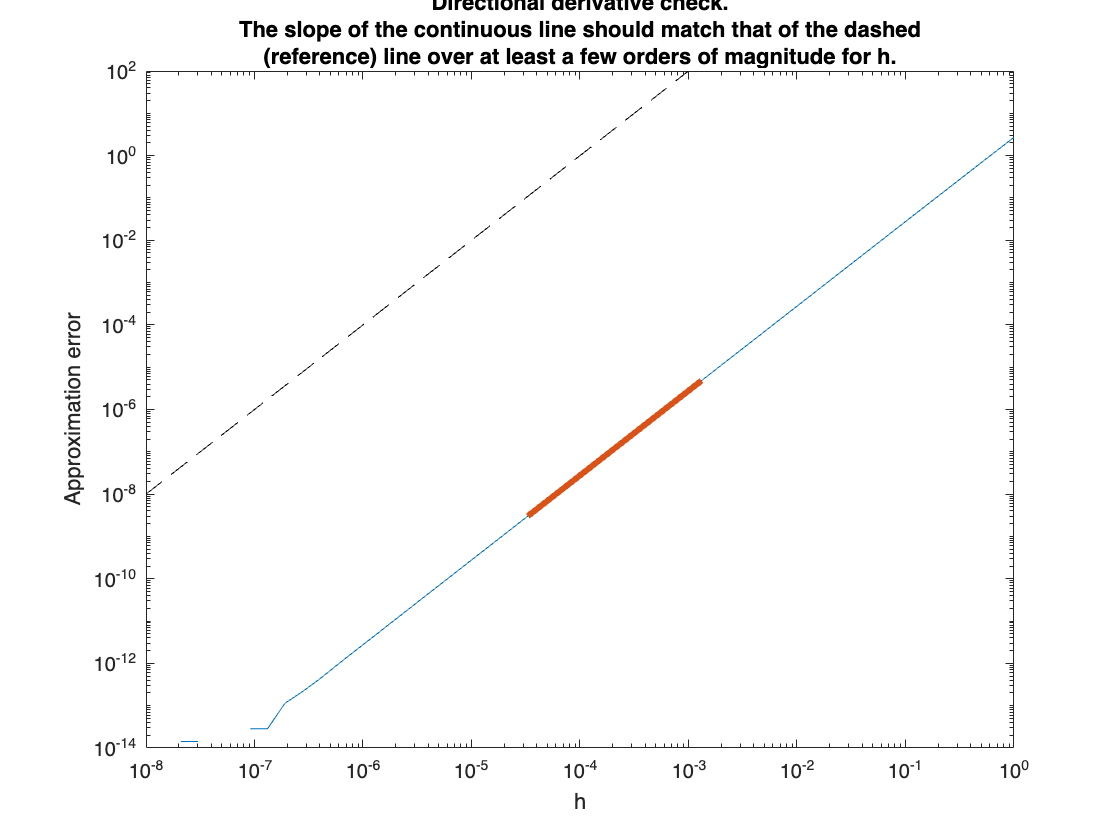

The slope should be 2. It appears to be: 1.99999.
If it is far from 2, then directional derivatives might be erroneous.


n=3; % data dimension
k=5; % number of matrices
p=n; % size of factorization X of barycenter B
r=n; % size of factorization Y of data A
A = data(n,k,r);
prob = nonconvex_problem(A,r,p);
checkdiff(prob);

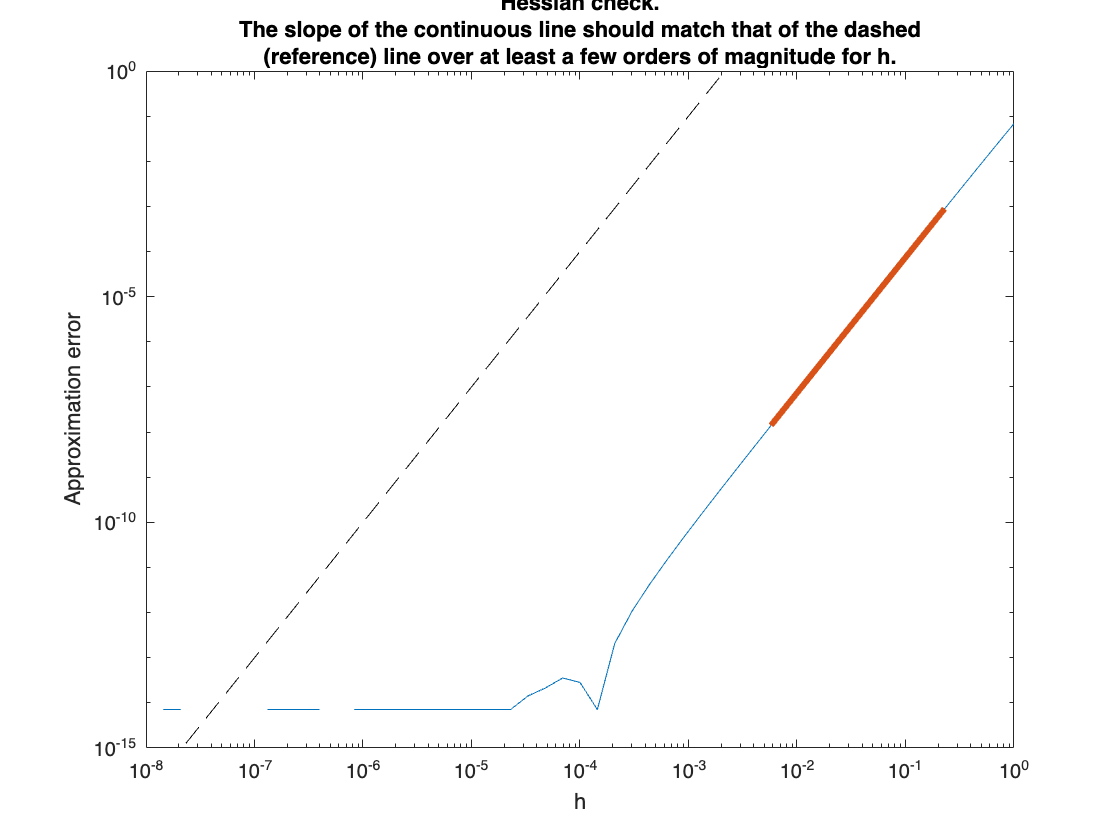

The slope should be 3. It appears to be: 3.00137.
If it is far from 3, then directional derivatives,
the gradient or the Hessian might be erroneous.
Tangency residual should be zero, or very close; residual: 6.40386e-11.
If it is far from 0, then the Hessian is not in the tangent space.
||a*H[d1] + b*H[d2] - H[a*d1+b*d2]|| should be zero, or very close.
	Value: 2.49017e-06 (norm of H[a*d1+b*d2]: 8.35028)
If it is far from 0, then the Hessian is not linear.
<d1, H[d2]> - <H[d1], d2> should be zero, or very close.
	Value: 2.15423 - 2.15424 = -3.63617e-06.
If it is far from 0, then the Hessian is not symmetric.

When using checkhessian with a finite difference approximation, the norm of the residual
should be compared against the norm of the gradient at the point under consideration (29).
Furthermore, it is expected that the FD operator is only approximately symmetric.
Of course, the slope can also be off.


checkhessian(prob)

[x, xcost, info, options] = trustregions(prob);

           iter                  cost val     grad. norm    numinner     hessvec   numstored   stopreason
              0   +2.1718676998472688e+01   1.579345e+01
acc TR+       1   +1.3949640414698598e+01   9.682361e+00           1           1           1   exceeded trust region
acc TR+       2   +7.7550784297210633e+00   3.586626e+00           2           2           2   negative curvature
acc           3   +5.8056059158634685e+00   7.962098e+00           2           2           2   exceeded trust region
acc           4   +2.2298715173225809e+00   7.020747e-01           3           3           2   reached target residual-kappa (linear)
REJ TR-       5   +2.2298715173225809e+00   7.020747e-01           8           8           4   negative curvature
acc TR+       6   +2.1308880912428245e+00   3.076065e-01           4           0           4   exceeded trust region
acc           7   +2.0727158749297354e+00   7.684185e-01           4           4           3   exceeded trust region
acc    

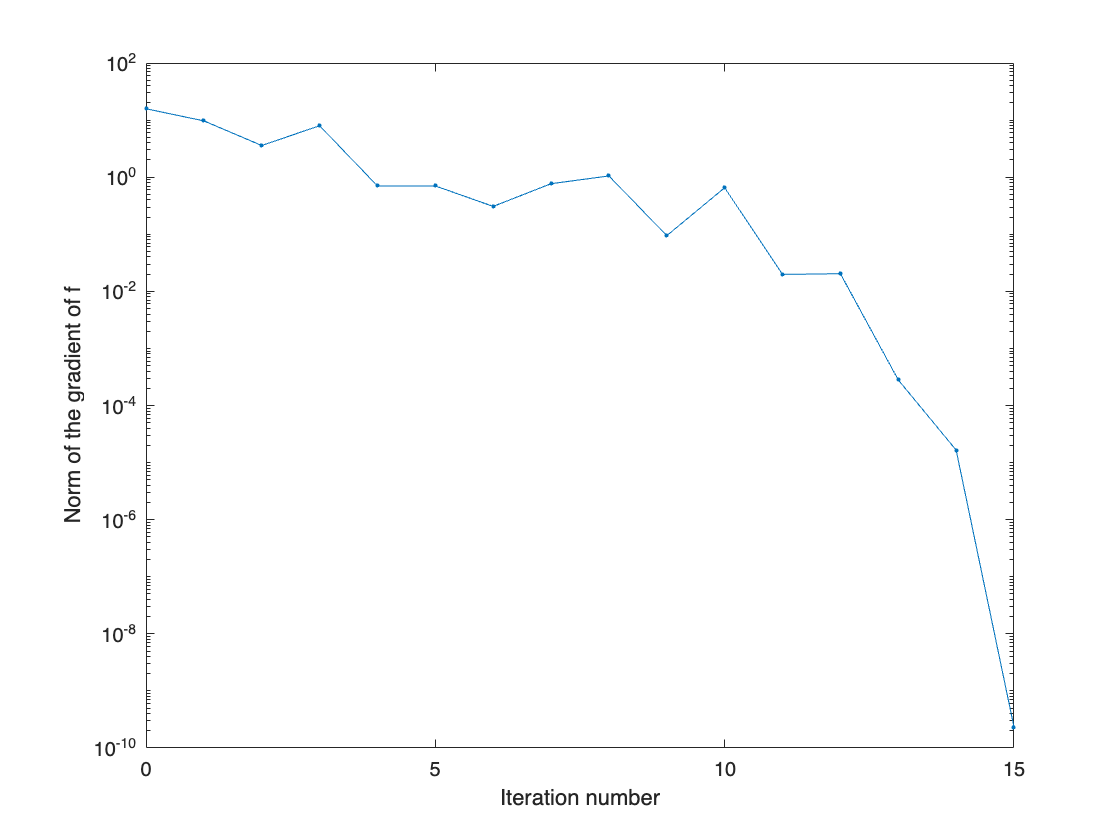

figure;
semilogy([info.iter], [info.gradnorm], '.-');
xlabel('Iteration number');
ylabel('Norm of the gradient of f');